%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ENG EC 503 (Ishwar) Fall 2023
% HW 8.2-8.3
% <Your full name and BU email>
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Kernel K-Means

clear, clc, close all,
rng('default');
defaultseed = rng;

%8.2
kmeans_dataset = "kernel-kmeans-2rings.mat";
svm_dataset = "kernel-svm-2rings.mat";



## 8.2

%{
load(svm_dataset)
%xyext
%Xy = [x' ones(size(x,2),1) y]
%Xy_1 = Xy(Xy(:,4)==1,:);
%Xy_2 = Xy(Xy(:,4)==-1,:);

Xy = [x' y]
Xy_1 = Xy(Xy(:,3)==1,:);
Xy_2 = Xy(Xy(:,3)==-1,:);

figure 
scatter(Xy_1(:,1), Xy_1(:,2), 'r', 'filled')
hold on
scatter(Xy_2(:,1), Xy_2(:,2), 'b', 'filled')
title("SVM Dataset")
hold off

%run SSGD Ksvm
t_max = 1000
nC = 256
ksigma = .5;
n = size(Xy,1)
Kij = zeros(n);
X = Xy(:,1:2);
for i = 1:size(Xy,1)
    for j = 1:size(Xy,1)
        Kij(i,j) = KRBF(X(i,:),X(j,:),ksigma);
    end
end
[psi_Xy, sample_norm_cost_gpsi_Xy, training_CCR_Xy, conf_mat_Xy]  = SSGDK(nC, t_max, ksigma, Xy, Kij);


disp("psi")
psi_Xy

disp('(8.2a): normalized loss')
figure
plot(sample_norm_cost_gpsi_Xy)
xlabel("iteration # = t*10")
title("The normalized loss for training set")
ylabel("Normalized loss")

figure
plot(sample_norm_cost_gpsi_Xy)
xlabel("iteration # = t*10")
title("The normalized loss for training set")
ylabel("Normalized loss")
ylim([0 100000000])

disp('(2b): Training CCR:')
figure
plot(training_CCR_Xy)
xlabel("iteration # = t*10")
title("The CCR for training set")
ylabel("CCR")

disp('(8.2c): Training confusion matrix:')
disp('rows are the predicted label, columns are actual label')
conf_mat_Xy

disp('(8.2d): Training set + boundary:')
figure 

% We will assign a color to each point in the mesh [x_min, x_max] x [y_min, y_max].
x_min = -2.5;
x_max = 2.5;
y_min = -2.5;
y_max = 2.5;
mesh_step_size = 0.05;
[xx,yy] = meshgrid(x_min:mesh_step_size:x_max,y_min:mesh_step_size:y_max);
%meshgrid_data = [reshape(xx,[],1),reshape(yy,[],1),ones(numel(xx),1)];
%inner_product_mesh = meshgrid_data * theta([indices,end],:);
% If do not include constant in decision, use the two lines below instead
% meshgrid_data = [reshape(xx,[],1),reshape(yy,[],1)];
% inner_product_mesh = meshgrid_data * theta(var,:);

xx_yy_grid = [reshape(xx,[],1) reshape(yy,[],1)];
%xx_yy_grid = [xx_yy_grid zeros(size(xx_yy_grid,1),199)];

xx_yy_data = zeros(size(xx_yy_grid,1),1);
%calculate based on psy'*Kjext
for i = 1:size(xx_yy_grid,1)
    for j = i:n
        xx_yy_data(i) = xx_yy_data(i) + psi_Xy(j) * KRBF(Xy(j,1:2), xx_yy_grid(i,:), ksigma);
    end
end
%xx_yy_data = xx_yy_data + psi_Xy(n+1)

xlim([x_min,x_max])
ylim([y_min,y_max])


reshape(xx_yy_data,size(xx))
contour(xx, yy, reshape(xx_yy_data,size(xx)), [0,0],'k','LineWidth',2);
%scatter(xx_yy_grid(:,1),xx_yy_grid(:,2), xx_yy_data, [],'s','fill');
hold on 
scatter(Xy_1(:,1), Xy_1(:,2), 'r')
scatter(Xy_2(:,1), Xy_2(:,2), 'b')
title("SVM Dataset & boundary")
xlabel('Feature 1');
ylabel('Feature 2');
hold off

datetime()

%}

## 8.3

## Load Data

choose which dataset to load (.mat files) dataset = "2-class-concentric"; % or "3-class-moon-data" K = 2; % number of clusters sigma = .16; % choice of bandwidth for rbf

load(kmeans_dataset)
K = 2;                          % number of clusters
sigma = 16;                     % choice of bandwidth for rbf
N = 500;                        % number of points per cluster

%load(dataset)
%plot(data(:,1), data(:,2), '*')
%title("Dataset")

## Vanilla K-means

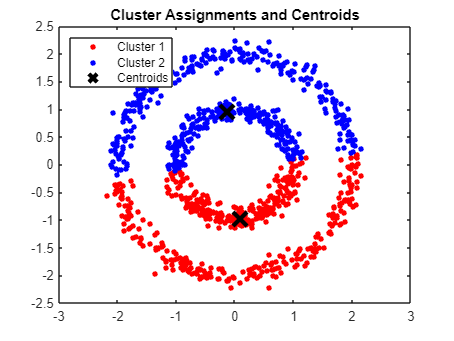

% TODO: create random initialization for mu
% [MU_final, WCSS, y_hat2] = k_means(Mu, data, N, K,2);
[idx, MU_final, WCSS] = kmeans(data, K);
figure;
plot(data(idx==1,1),data(idx==1,2),'r.','MarkerSize',12)
hold on
plot(data(idx==2,1),data(idx==2,2),'b.','MarkerSize',12)
plot(MU_final(:,1),MU_final(:,2),'kx',...
     'MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Centroids',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
hold off

## Kernel K-means

% TODO: create random initialization for alpha

Alpha = rand(2)

Alpha =     0.1270    0.6324
    0.9134    0.0975



[Alpha_final, WCSS, y_hat] = kernel_k_means(Alpha, [data idx], N, K, sigma);

nl =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


datalabels =    -0.6365    0.7959    2.0000
   -0.2710    0.9421    2.0000
   -0.8235    0.2490    2.0000
    0.8079    0.2905    2.0000
   -1.0049    0.1613    2.0000
    1.1978   -0.2264    1.0000
   -0.1130   -0.9850    1.0000
    0.5589   -0.8574    1.0000
    0.0869   -1.0240    1.0000
    1.0029   -0.2298    1.0000


data =    -0.6365    0.7959
   -0.2710    0.9421
   -0.8235    0.2490
    0.8079    0.2905
   -1.0049    0.1613
    1.1978   -0.2264
   -0.1130   -0.9850
    0.5589   -0.8574
    0.0869   -1.0240
    1.0029   -0.2298


ans = 1.0387

Iteration: 1


ans =     0.1270    0.6324


ans =     0.1270    0.6324


ans =     0.9134    0.0975


ans =     0.9134    0.0975



Converged.


WCSS = 0

Unrecognized function or variable 'WCSoS'.

Error in dkechris_hw8_32>kernel_k_means (line 377)
                WCSS = WCSS + WCSoS(alpha_current(i,:),Xyi);

Alpha_final
figure;
plot(data(y_hat==1,1),data(y_hat==1,2),'r.','MarkerSize',12)
hold on
plot(data(y_hat==2,1),data(y_hat==2,2),'b.','MarkerSize',12)
plot(Alpha_final(:,1),Alpha_final(:,2),'kx',...
     'MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Centroids',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
hold off

function [psi, sample_norm_cost_gpsi, training_CCR, conf_map]  = SSGDK(nC, t_max, ksigma, XY, Kij)
    %can replace 2/3 with size-1 and size dim2 respectively for any size x
    n = size(XY,1);
    psi = zeros(n + 1,1);
    X = XY(:,1:2);
    Ylabel = XY(:,3);
    datetime()
    sample_norm_cost_gpsi = zeros(t_max/10,1);
    training_CCR = zeros(t_max/10,1);
    %test_CCR = zeros(t_max/10,1);

    %should be a 2x1
    KK = X * X';
    % Kij


    for iii = 1:t_max
        % current iteration index
        t = iii; 
        st = .256/t;
        % choose sample index:   
        j = randi(n);
        xj = XY(j,1:2);
        %xjext = [XY(j,1:2) 1];
        %Kjzero = zeros(size(XY,1),1)
        %Kjext = [zeros(size(XY,1),2) ones(size(XY,1),1)]
        %for i = 1:n
        %    Kjext(i,j) = KRBF(X(i,:),xj,ksigma);
        %end
        Kjext = [Kij(:,j)' 1];
        yj = XY(j,3);
        
        % compute subgradient:
        % v with Id for d=3   
        KKzero = [KK zeros(size(KK,1),1); zeros(1, (size(KK,1)+1))];
        v = [KK zeros(size(KK,1),1); zeros(1, (size(KK,1)+1))] * psi;
        psi;
        Kjext(1,:);
        if yj * psi' * Kjext' < 1
            v = v - nC * yj * Kjext';
        end
        % update parameters:
        psi = psi - st*v;
        
        % redefine parameters
        
        if (mod(t,10) == 0)
            %Ylabel
            %psi'
            %X'
            %Xext'*theta'
            %Xext' * theta' * Ylabel
            %Ylabel .* (psi' * X')'
            %sum( nC * Ylabel .* (psi' * X')')
            %C * max(0,1 - Ylabel * theta' * Xext')
            %sum(C * max(0,1 - Ylabel * theta' * Xext'))
            %sum(sum(transpose(C * max(0,1 - ylabel * theta' * text'))))
            %sample_norm_cost(t/10,1) = norm(theta(1:2))/2 + sum(transpose(C * max(0,1 - Ylabel * theta' * Xext')));
            disp("sample norm cost calc");
            psi;
            psi';
            fgpsi = 1/2 * psi' * KKzero * psi;
            fjsum = 0;
            Kij(:,j);
            for j = 1:n
                fjsum = fjsum + nC * max(0, yj * psi'*[Kij(:,j); 1]);
            end
            sample_norm_cost_gpsi(t/10,1) = fgpsi + fjsum;
            
            % Training CCR:
            training_CCR(t/10,1) = kernel_CCR(psi, Kij, Ylabel);
            % Test CCR:
            % test_CCR(t/1000,1) = tCCR(psi, Xtestext, Ytestlabel);

            
        end
    end
    conf_map = conf_mat_ker(XY, psi, Kij)
    datetime() 
end

function output = KRBF(u, v, ksigma)
    output = exp(-1 * norm(u - v).^2 /(2*ksigma.^2));
end

function CCR = kernel_CCR(psi, Kij, Ylabel)
    CCR = 0;
    n = size(Ylabel,1);
    % y_predict = sign(psi'*Xext')';
    % CCR = sum(y_predict == Ylabel) / n;
    for j = 1:n
        psi;
        Kij(:,j);
        if Ylabel(j,1) == sign(psi'*[Kij(:,j); 1])
            CCR = CCR + 1;
        end
    end
    CCR = CCR / n;
end

function sign = xy_predict(psi, Kij, xtest)
    CCR = 0;
    n = size(Ylabel,1);
    % y_predict = sign(psi'*Xext')';
    % CCR = sum(y_predict == Ylabel) / n;
    for j = 1:n
        psi;
        Kij(:,j);
        if Ylabel(j,1) == sign(psi'*[Kij(:,j); 1])
            CCR = CCR + 1;
        end
    end
    CCR = CCR / n;
end

function conf_mat = conf_mat_ker(XY, psi, Kij)
% function takes 2 data sets, w and b
% returns the correct classification rate of the data using +/-w and b
% returns a confusion matrix where the rows are the predicted rows and the
% columns are the correct columns
    n = size(XY,1);
    X = XY(:,1:2);
    label = XY(:,3);
    conf_mat = zeros(3);
    
    % calc conf map
    for j = 1:n
        yj = sign(psi'*[Kij(:,j); 1]);
        yactual = label(j,1);
        conf_mat(yj+2,yactual+2) = conf_mat(yj+2,yactual+2) + 1;
    end
    conf_mat(2,:) = [];
    conf_mat(:,2) = [];
end

%here
function [alpha_current, WCSS, yhat] = kernel_k_means(Alpha, data, N, K, sigma);
    alpha_previous = Alpha;
    alpha_current = Alpha;
    nl = zeros(N,1)
    datalabels = data
    data = data(:,1:2)

    KK = data * data';
    
    Kij = zeros(N);
    data(1,:)*data(1,:)'
    for i = 1:size(data,1)
        for j = 1:size(data,1)
            Kij(i,j) = data(i,:)*data(j,:)';
        end
    end
    % initializations
    yhat = ones(size(data,1),1);
    converged = 0;
    iteration = 0;
    convergence_threshold = 0.025;

    while (converged==0)
        alpha_previous = alpha_current;
        iteration = iteration + 1;
        fprintf('Iteration: %d\n',iteration)

        for i = 1:N
            bestval = 0;
            for u = 1:K
                %curval = (data(i,:)-alpha_current(u,:))*KK*(data(i,:)-alpha_current(u,:))';
                curval = (data(i,:)-alpha_current(u,:))*(data(i,:)-alpha_current(u,:))';
                if curval > bestval
                    bestval = curval;
                    bestu = u;
                end
            end
            yhat(i) = bestu;
        end


        for u = 1:K
            nl(u) = 0;
            for i = 1:N
                if yhat(i) == u
                    nl(u) = nl(u) + 1;
                end
            end
        end

        for u = 1:K
            if nl(u) ~= 0
                sumej = 0;
                for i = 1:N
                    if yhat(i) == u
                        sumej = sumej + data(i,:);
                    end
                end
                sumej = 0/N;
            else
                j = randi(N);
                alpha_current(u,:) = data(j,:);
            end
        end

        largestdelta = large_diff(alpha_previous,alpha_current);
        if (largestdelta < convergence_threshold)
            converged=1;
        end
    
        %CODE 5 - Plot clustering results if converged:
        if (converged == 1)
            fprintf('\nConverged.\n')
            
            %If converged, get WCSS metric
            %sum of all distances^2 for each point in cluster
            WCSS = 0

            for i = 1:K
                Xyi = datalabels(datalabels(:,3)==i,:);
                WCSS = WCSS + WCSoS(alpha_current(i,:),Xyi);
            end
            
            if k == 3
                Xy1 = datalabels(datalabels(:,3)==1,:);
                Xy2 = datalabels(datalabels(:,3)==2,:);
                Xy3 = datalabels(datalabels(:,3)==3,:);
                scatter(Xy1(:,1),Xy1(:,2),"red")
                hold on
                scatter(Xy2(:,1),Xy2(:,2),"green")
                scatter(Xy3(:,1),Xy3(:,2),"blue")
                scatter(alpha_current(:,1),alpha_current(:,2),"black")
                hold off
            else
                datalabels = sortrows(datalabels,3)
                scatter(datalabels(:,1),datalabels(:,2),[],datalabels(:,3))
                hold on
                scatter(alpha_current(:,1),alpha_current(:,2),"black")
                colormap("jet")
                hold off
            end


        end
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end
end

%functions from HW7
function [theta, sample_norm_cost, training_CCR, test_CCR]  = SSGD(C, t_max, XY_train, XY_test)
    theta = [0; 0; 0];
    n = size(XY_train,1);
    Xext = XY_train(:,1:3)
    Ylabel = XY_train(:,5)
    Xtestext = XY_test(:,1:3)
    Ytestlabel = XY_test(:,5)
    datetime()
    sample_norm_cost = zeros(t_max/1000,1)
    training_CCR = zeros(t_max/1000,1);
    test_CCR = zeros(t_max/1000,1);

    for iii = 1:t_max
        % current iteration index
        t = iii; 
        st = .5/t;
        % choose sample index:   
        j = randi(n);
        xjext = XY_train(j,1:3);
        yj = XY_train(j,5);
        
        % compute subgradient:
        % v with Id for d=2   
        v = [theta(1:2,1); 0];
        if yj * theta' * xjext' < 1
            v = v - n * C * yj * xjext';
        end
        % update parameters:
        theta = theta - st*v;
        
        % redefine parameters
        
        if (mod(t,1000) == 0)
            Ylabel;
            theta';
            Xext';
            %Xext'*theta'
            %Xext' * theta' * Ylabel
            Ylabel .* (theta' * Xext')';
            sum( C * Ylabel .* (theta' * Xext')');
            %C * max(0,1 - Ylabel * theta' * Xext')
            %sum(C * max(0,1 - Ylabel * theta' * Xext'))
            %sum(sum(transpose(C * max(0,1 - ylabel * theta' * text'))))
            %sample_norm_cost(t/1000,1) = norm(theta(1:2))/2 + sum(transpose(C * max(0,1 - Ylabel * theta' * Xext')));
            sample_norm_cost(t/1000,1) = norm(theta(1:2))/2 + sum( C * Ylabel .* (theta' * Xext')');
            
            % Training CCR:
            training_CCR(t/1000,1) = tCCR(theta, Xext, Ylabel);
            % Test CCR:
            test_CCR(t/1000,1) = tCCR(theta, Xtestext, Ytestlabel);

            
        end
    end
   datetime() 
end

function CCR = tCCR(theta, Xext, Ylabel)
    CCR = 0;
    n = size(Xext,1);
    y_predict = sign(theta'*Xext')';
    CCR = sum(y_predict == Ylabel) / n;
    %for i = 1:n
    %    if Ylabel(i,1) == sign(theta'*Xext(i,:)')
    %        CCR = CCR + 1
    %    end
    %end
    %CCR = CCR / n
end

function conf_mat = conf_mat_bin(XY, theta)
% function takes 2 data sets, w and b
% returns the correct classification rate of the data using +/-w and b
% returns a confusion matrix where the rows are the predicted rows and the
% columns are the correct columns
    n = size(XY,1);
    x_ext = XY(:,1:3);
    label = XY(:,5);
    conf_mat = zeros(3);
    
    % calc conf map
    for j = 1:n
        xj = x_ext(j,:)';
        yj = sign(theta' * xj);
        yactual = label(j,1);
        conf_mat(yj+2,yactual+2) = conf_mat(yj+2,yactual+2) + 1;
    end
    conf_mat(2,:) = [];
    conf_mat(:,2) = [];
end

function largestdiff = large_diff(a1, a2)
% take an array of points, a1 and a2, where both are the same dim X:2
% outputs the largest difference between the distance of each set in a1-a2 array 
% if not same size, outputs 1
    if size(a1) == size(a2)
        adist = zeros(size(a1,1));
        %calculate distance for each row of points
        for i = 1:size(a1,1)
            a1(i,:)
            a2(i,:)
            adist(i) = dist(a1(i,:),a2(i,:)');
        end
        %take largest of distances
        largestdiff = max(adist);
    else
        largestdiff = 1
    end
end